**DataExplorer App**

Purpose

DataExplorer is a multi-purpose app for plotting data from Epochs, Datasets and Cells. It replaces the functionality of the TreeBrowserGUI in our precviuos analysis package. You can load a set results from Epochs, Datasets, or Cells into the App, select a Plotter function, and click through the list to see the Plotter applied to each item. You can also export Results to .h5 files from the App.

Opening the App

Open the App by calling it from the command line.

DataExplorer;

 0:  vfsmdatajoint01.fsm.northwestern.edu via TCP/IP   Server version 8.0.20 (encrypted)


You will see a window that looks something like this.

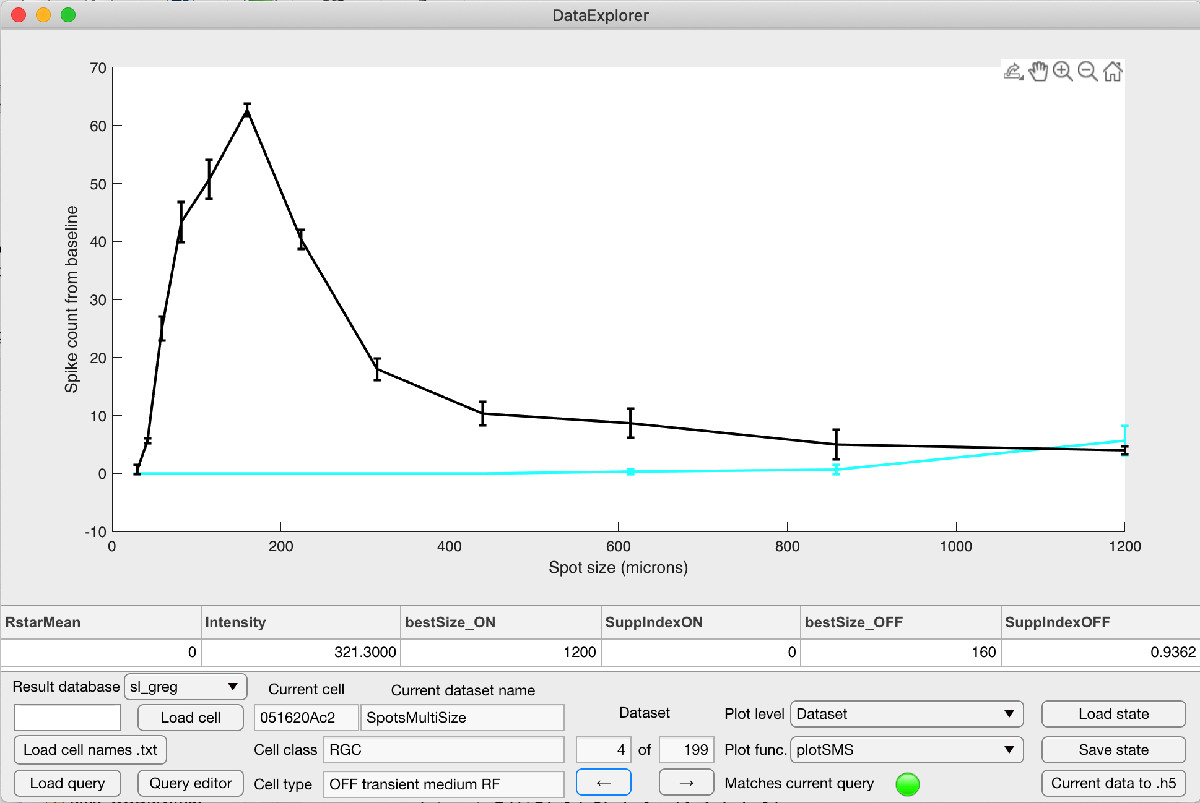

A browser for Results

Unlike AnalysisPipelineBuilder, which takes Datasets as input (though its input data query), DataExplorer's input is Results. You can load cell_ids either one at a time with the "Load cell" button or from a .txt file with the "Load cell names .txt" button, or you can create a query with the QueryBuilder. But you are not really loading the Cells or the Datasets, but rather their Results entries. Thus, the Results need to be computed and stored in the database for you to browse them in the App. 

Result database chooser

Recall that Results tables are stored within the schema for each user, but they are all readable to everyone. Therefore, you need to select which database you want to search. Your optioons will be in a dropdown menu at the top left of the control panels in the bottom third of the window. It will default to your own database schema.

Plot level selector

The "Plot level" dropdown menu allows you to select whether you want to browse over Epochs, Datasets, or Cells. This will determine both the Plotter functions availalbe (in the dropdown menu below) and the set of items to browse. 

Plot function selector

This dropdown menu will populate from 2 folders. The first set of functions are those that appear in your 'user_epoch_plotters_folder', 'user_dataset_plotters_folder', or 'user_cell_plotter_folder', depending on the selected plot level. See the FolderSetup document for instructions on setting up these folders. These functions willl be followed by a '--------------------' divider and then by the shared plotting functions in [getenv('DJ_root') / plotting_functions']. There is (or will be) a separate document on writing plotter functions. You can look at the examples in the folder. 

Item scroll

In the center of the control area in the example window above, you will see the words "Dataset" and 4 of 199. This top word is the item type. It will be either Epoch, Dataset, or Cell, depending on the Plot level selector. The arrows let you scroll through the items, and the left edit box (with the 4 in it) is editable, so you can jump to a different item. 

Plot area

The plot area takes up the top part of the App window. It will automatically be subdivied into multiple axes if your Plotter function takes multiple axes as inputs. Use the data computed in the Epoch, Dataset, or Cell Result to plot anything you want with standard MATLAB plotting commands. There is (or will be) a separate document on writing plotter functions. You can look at the examples in the folder. 

Result table

Any result fields you would llike to see along with your plots can be returned as a struct from your Plotter function, and they will appear in this table below the plot. If you don't return anything, the table will be blank.

Load / Save state buttons

These buttons allow you to save or load the full state of the App, including the item set, database, and plotter function. The buttons will open up a dialog box to save/load a .mat file. The default folder for these saved states is one of the folders explained in the FolderSetup document. NOTE: These are .mat files saved outside the database.

Current data to .h5 button

This button allows you to export the Epoch, Dataset or Cell Result you are currently viewing to an hdf5 file for Igor. It will save a file in your current directory with the name of the cell. More complex and automated hdf5 exporting is covered in the Hdf5Exporter document (under construction) referenced along with AnalysisPipelineBuilder. 